# Filter Implementation

## Load Data

%Example of Signals
load("Signals.mat")

%Equiripple FIR LP Coefficients
load("Equiripple_LP_Coeffs.mat")

%Butterworth IIR LP Coefficients
load("ButterworthCoeffs.mat")
[b,a] = sos2tf(SOS, G);

## Processing Data Equiripple (FIR)

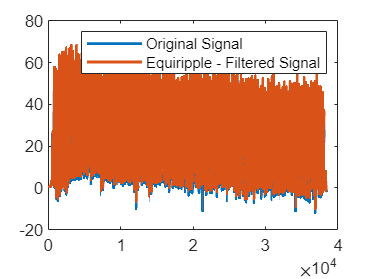

x = Signals.IMU_right_knee_angle;
y = zeros(size(x));

coeff = flip(Num);

for i=length(Num):length(x)
    y(i) = sum( x(i-length(Num)+1:i) .* coeff' );
end


figure;
plot(x, 'Linewidth', 1.5)
hold on
plot(y, 'Linewidth', 1.5)
legend('Original Signal', 'Equiripple - Filtered Signal')

## Processing Data Butterworth (IIR)

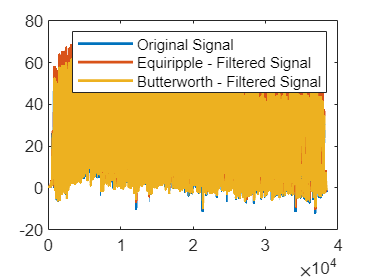

y2 = zeros(size(x));

for i=length(a):length(x)
    
    parte_x = b(1)*x(i) + b(2)*x(i-1) + b(3)*x(i-2) + b(4)*x(i-3) + b(5)*x(i-4) + b(6)*x(i-5) + b(7)*x(i-6) + b(8)*x(i-7) + b(9)*x(i-8) + b(10)*x(i-9) + b(11)*x(i-10);
    parte_y = a(2)*y2(i-1) + a(3)*y2(i-2) + a(4)*y2(i-3) + a(5)*y2(i-4) + a(6)*y2(i-5) + a(7)*y2(i-6) + a(8)*y2(i-7) + a(9)*y2(i-8) + a(10)*y2(i-9) + a(11)*y2(i-10);
    
    y2(i) = (parte_x - parte_y)/a(1);
end

figure;
plot(x, 'Linewidth', 1.5)
hold on
plot(y, 'Linewidth', 1.5)
hold on
plot(y2, 'Linewidth', 1.5)
legend('Original Signal', 'Equiripple - Filtered Signal', 'Butterworth - Filtered Signal')

## Print Matlab Array

% Display the MATLAB array in a format that can be copied to Arduino
% fprintf('int filter_array[] = {');
% for i = 1:length(coeff)
%     fprintf('%d', coeff(i));
%     if i < length(coeff)
%         fprintf(', ');
%     end
% end
% fprintf('};\n');


% Define a format specifier to display the numbers without scientific notation
%formatSpec = 'float myArray[] = {%.15f, %.15f, %.15f, %.15f, %.15f, %.15f, %.15f, %.15f, %.15f, %.15f, %.15f};\n';

% Print the array in the desired format
%fprintf(formatSpec, b);


## Change Code to use in Arduino

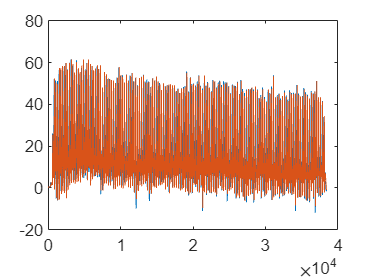

% y2 = zeros(size(x));
% 
% for i=length(a):length(x)
%     
%     parte_x = b(1)*x(i) + b(2)*x(i-1) + b(3)*x(i-2) + b(4)*x(i-3) + b(5)*x(i-4) + b(6)*x(i-5) + b(7)*x(i-6) + b(8)*x(i-7) + b(9)*x(i-8) + b(10)*x(i-9) + b(11)*x(i-10);
%     parte_y = a(2)*y2(i-1) + a(3)*y2(i-2) + a(4)*y2(i-3) + a(5)*y2(i-4) + a(6)*y2(i-5) + a(7)*y2(i-6) + a(8)*y2(i-7) + a(9)*y2(i-8) + a(10)*y2(i-9) + a(11)*y2(i-10);
%     
%     y2(i) = (parte_x - parte_y)/a(1);
% end

% Obtain sensor data
filter_b_coeffs = [0.00000000001763868255795996588066653, 0.00000000017638682557959965880666533, 0.00000000079374071510819850340408520, 0.00000000211664190695519600907756054, 0.00000000370412333717159301588573094, 0.00000000444494800460591145362675462, 0.00000000370412333717159301588573094, 0.00000000211664190695519600907756054, 0.00000000079374071510819850340408520, 0.00000000017638682557959965880666533, 0.00000000001763868255795996588066653];

%b; % [0.000000000017639, 0.000000000176387, 0.000000000793741, 0.000000002116642, 0.000000003704123, 0.000000004444948, 0.000000003704123, 0.000000002116642, 0.000000000793741, 0.000000000176387, 0.000000000017639];
filter_a_coeffs = [1.00000000000000000000000000000000000, -8.86539185488674519319829414598643780, 35.42604836507283039281901437789201736, -84.02183152140842992139369016513228416, 130.97706354885895052575506269931793213, -140.21143437986074786749668419361114502, 104.38304669722462847403221530839800835, -53.36061350244294487765728263184428215, 17.92518016645301770495279924944043159, -3.57295484601243673594694882922340184, 0.32088734506391514145207111141644418];

%a; %[1, -8.865392, 35.42605, -84.02183, 130.9771, -140.2114, 104.3830, -53.36061, 17.92518, -3.572955, 0.3208873];
x_array = zeros(11,1);
y_array = x_array;

saida = [];

for i=1:length(x)
    
    x_ard = x(i);
    
    if i<11
        
        x_array(1) = x_ard;
        y_array(1) = 0;
        
        for j = 10:-1:1
            x_array(j + 1) = x_array(j);
            y_array(j + 1) = y_array(j);
        end
        
        
    else
        
        x_array(1) = x_ard;
        
        % Calculate parte_x
        parte_x = 0;
        for z = 1:11
            parte_x = parte_x + (filter_b_coeffs(z) * x_array(z));
        end
        
        
        % Calculate parte_y
        parte_y_temp = 0; % Separate variable for intermediate calculations
        for w = 2:11
            parte_y_temp = parte_y_temp + (filter_a_coeffs(w) * y_array(w));
        end
        
        y_array(1) = parte_x - parte_y_temp / filter_a_coeffs(1);
        saida = [saida y_array(1)];
        
        for k = 10:-1:1
            x_array(k + 1) = x_array(k);
            y_array(k + 1) = y_array(k);
        end
        
    end
end

figure
plot(x)
hold on
plot(saida)



%ARDUINO
%     if (count<11){
% 
%       x_array[0] = x;
%       y_array[0] = 0;
% 
%       // Update the arrays for the next iteration
%       for (int j = 10; j > 0; j--) {
%         x_array[j] = x_array[j - 1];
%         y_array[j] = y_array[j - 1];
%       }
% 
%       count = count+1;
%       
%     }else{
%       x_array[0] = x;
%       
%       // Calculate parte_x
%       parte_x = 0;
%       for (int z = 0; z < 11; z++) {
%         parte_x = parte_x + ( filter_b_coeffs[z] * x_array[z] );
%       }
% 
%       // Calculate parte_y
%       parte_y = 0;
%       for (int w = 1; w < 11; w++) {
%        parte_y = parte_y + (filter_a_coeffs[w] * y_array[w]);
%       }
% 
% 
%       y_array[0] = (parte_x - parte_y) / filter_a_coeffs[0];
% 
%       Serial.println(y_array[0], 35);
% 
%       // Update the arrays for the next iteration
%       for (int k = 10; k > 0; k--) {
%         x_array[k] = x_array[k - 1];
%         y_array[k] = y_array[k - 1];
%       }
%       
%       
%     }    


## High Pass Filter

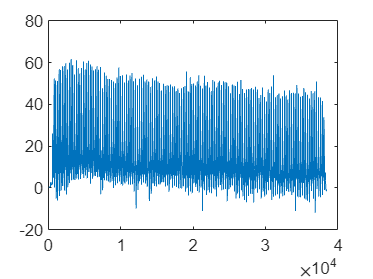

y3 = zeros(size(x));

for i=2:length(x)
    y3(i) = x(i)-x(i-1) + 0.99995*y3(i-1);
end

figure
plot(x)
hold on

lot(y3)

Unrecognized function or variable 'lot'.